첫번째 cycle의 충전전류를 얻는다.

load ryan3_gen_data.mat

idx = 1; % idxAll; 

battery_dataset(idx).Ic

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002   

battery_dataset(idx).Ic(1,:)

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999


% 열벡터로 바꾼다.
Ic1 = battery_dataset(idx).Ic(1,:)'

Ic1 =          0
    4.3998
    4.4002
    4.4002
    4.4003
    4.3998
    4.3999
    4.4003
    4.4001
    4.4003


cycle_div = 50;
chargeCurrentIndex = linspace(0,1.2,100)

chargeCurrentIndex =          0    0.0121    0.0242    0.0364    0.0485    0.0606    0.0727    0.0848    0.0970    0.1091    0.1212    0.1333    0.1455    0.1576    0.1697    0.1818    0.1939    0.2061    0.2182    0.2303    0.2424    0.2545    0.2667    0.2788    0.2909    0.3030    0.3152    0.3273    0.3394    0.3515    0.3636    0.3758    0.3879    0.4000    0.4121    0.4242    0.4364    0.4485    0.4606    0.4727    0.4848    0.4970    0.5091    0.5212    0.5333    0.5455    0.5576    0.5697    0.5818    0.5939


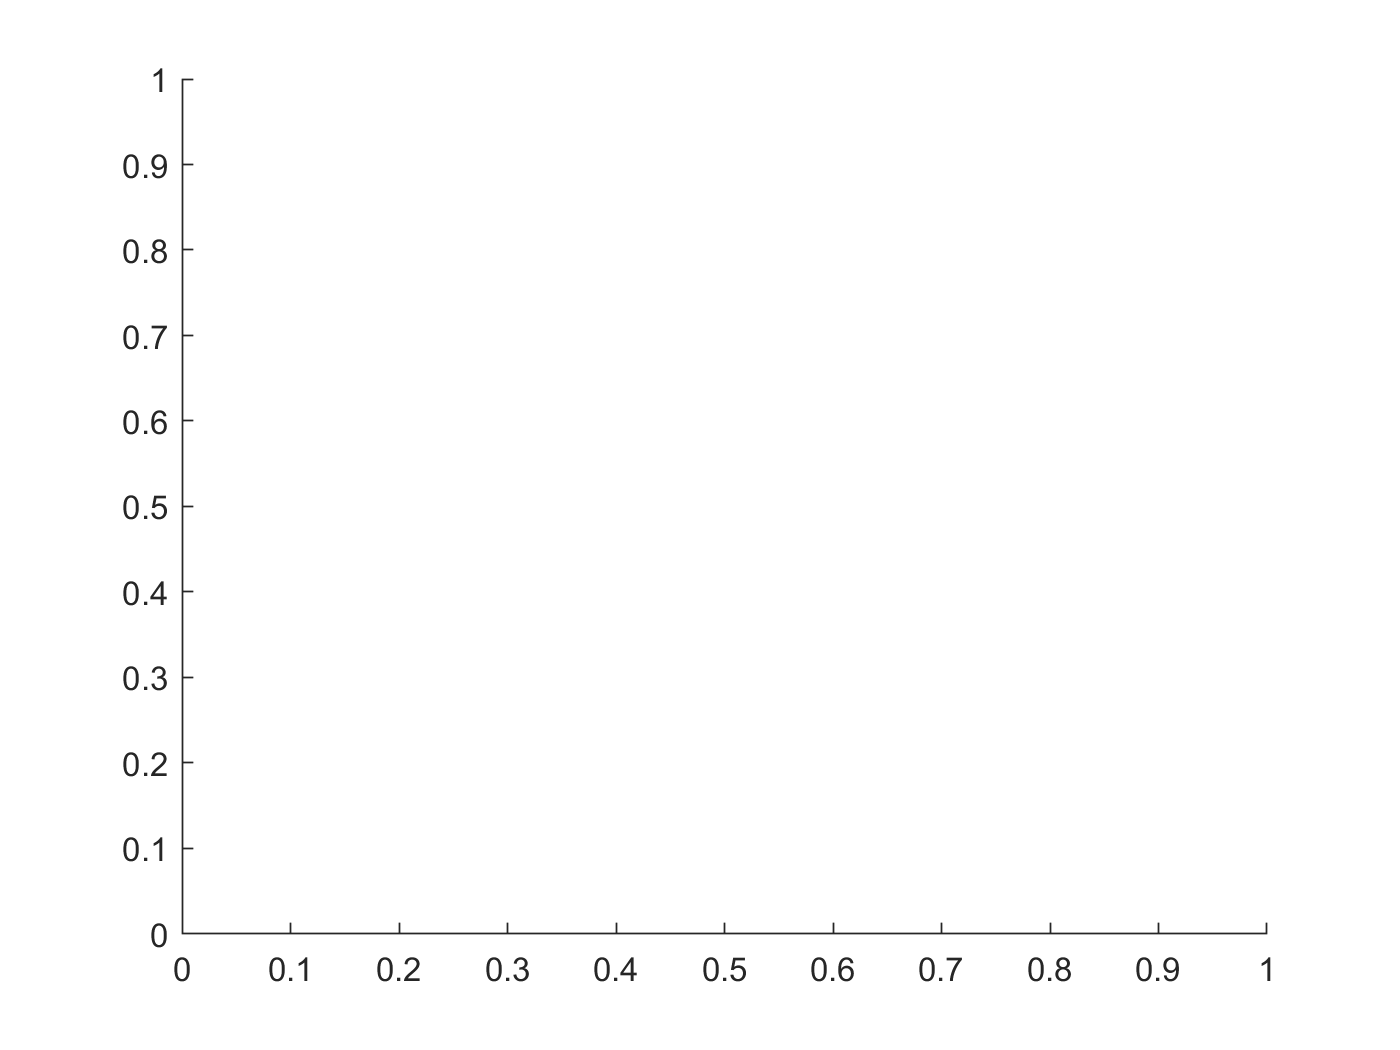

figure, hold on

for i = 1 : length(battery_dataset(1).Ic)
    if rem(i,cycle_div) == 0
    plot(chargeCurrentIndex,battery_dataset(1).Ic(i,:))
    end 
end
hold off

% 전체 데이타에 대해서 
IcFirst = zeros()

IcFirst = 0

IcFirst = battery_dataset(1).Ic(1,:)

IcFirst =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999


%IcFirst = battery_dataset(2).Ic(1,:)
for i=1:length(battery_dataset)
    IcFirst(i,:) = battery_dataset(i).Ic(1,:);
end
IcFirst

IcFirst =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.800

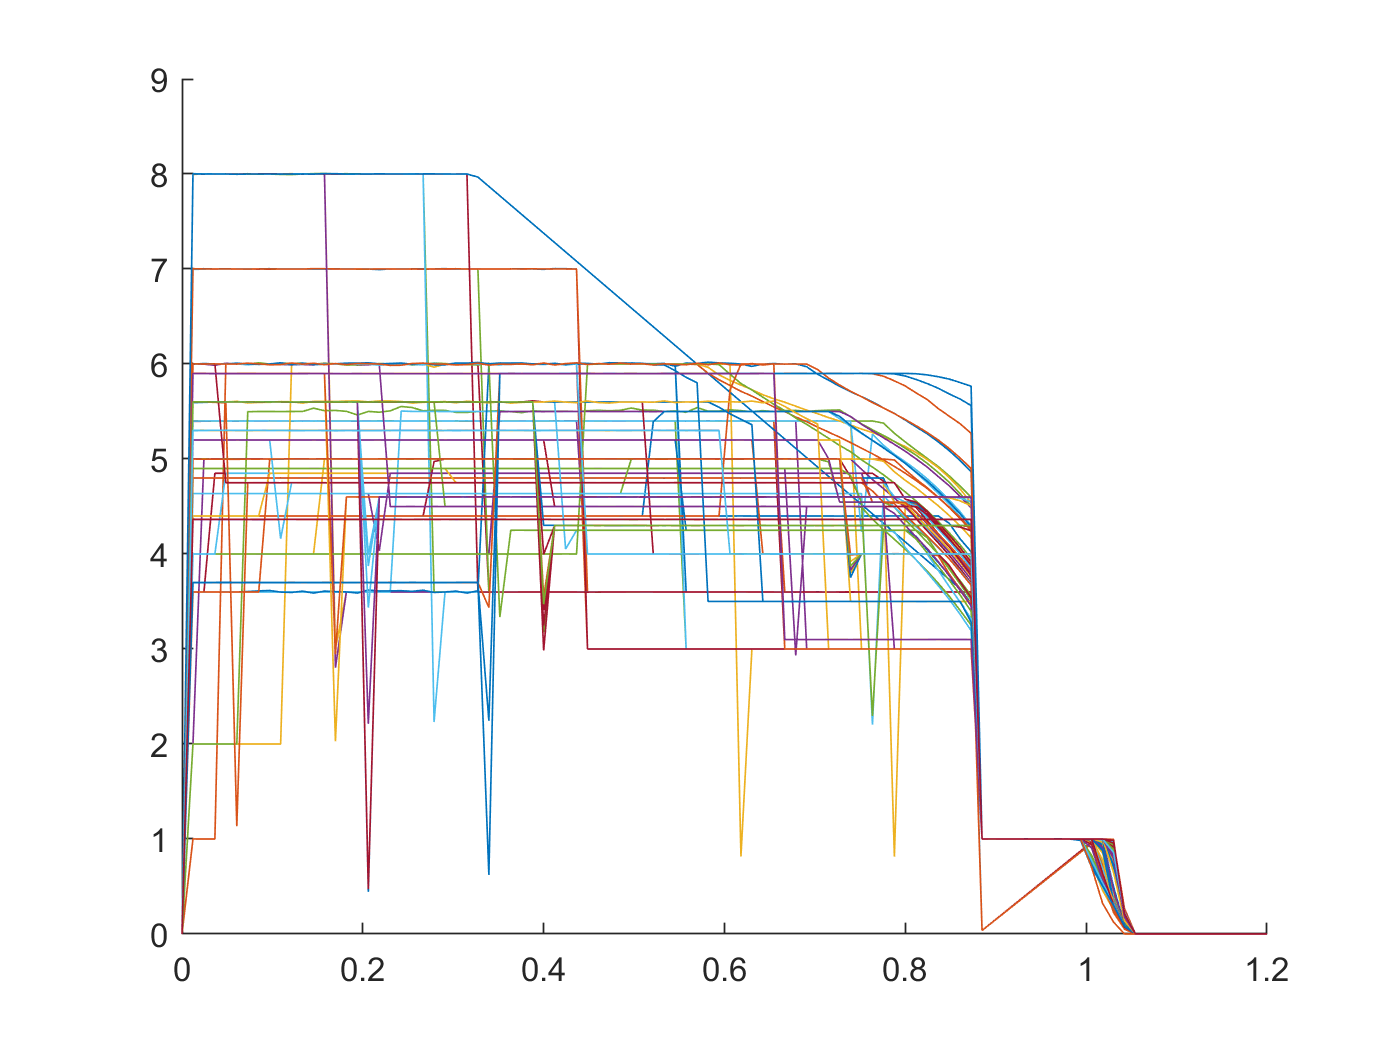

figure, hold on
for i = 1 : length(IcFirst)
    %if rem(i,2) == 0
    plot(chargeCurrentIndex,IcFirst(i,:)) % movmean
    %end 
end
hold off

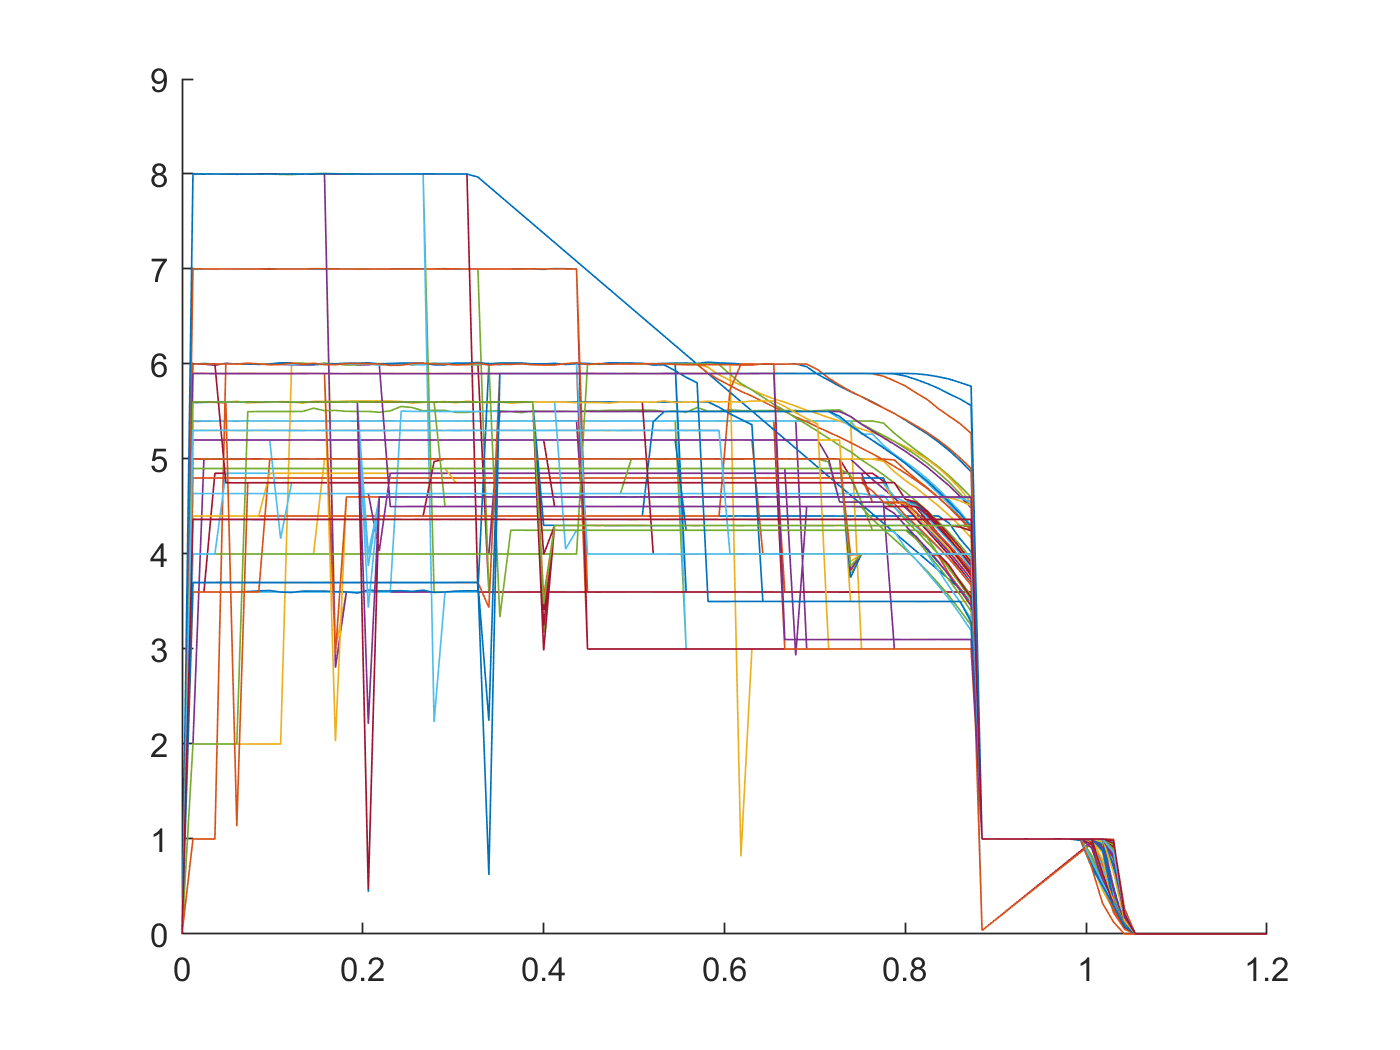

figure, hold on
for i = 1 : length(IcFirst)
    %if rem(i,2) == 0
    plot(chargeCurrentIndex,filloutliers(IcFirst(i,:),'nearest','movmedian',3)) % movmean
    %end 
end
hold off

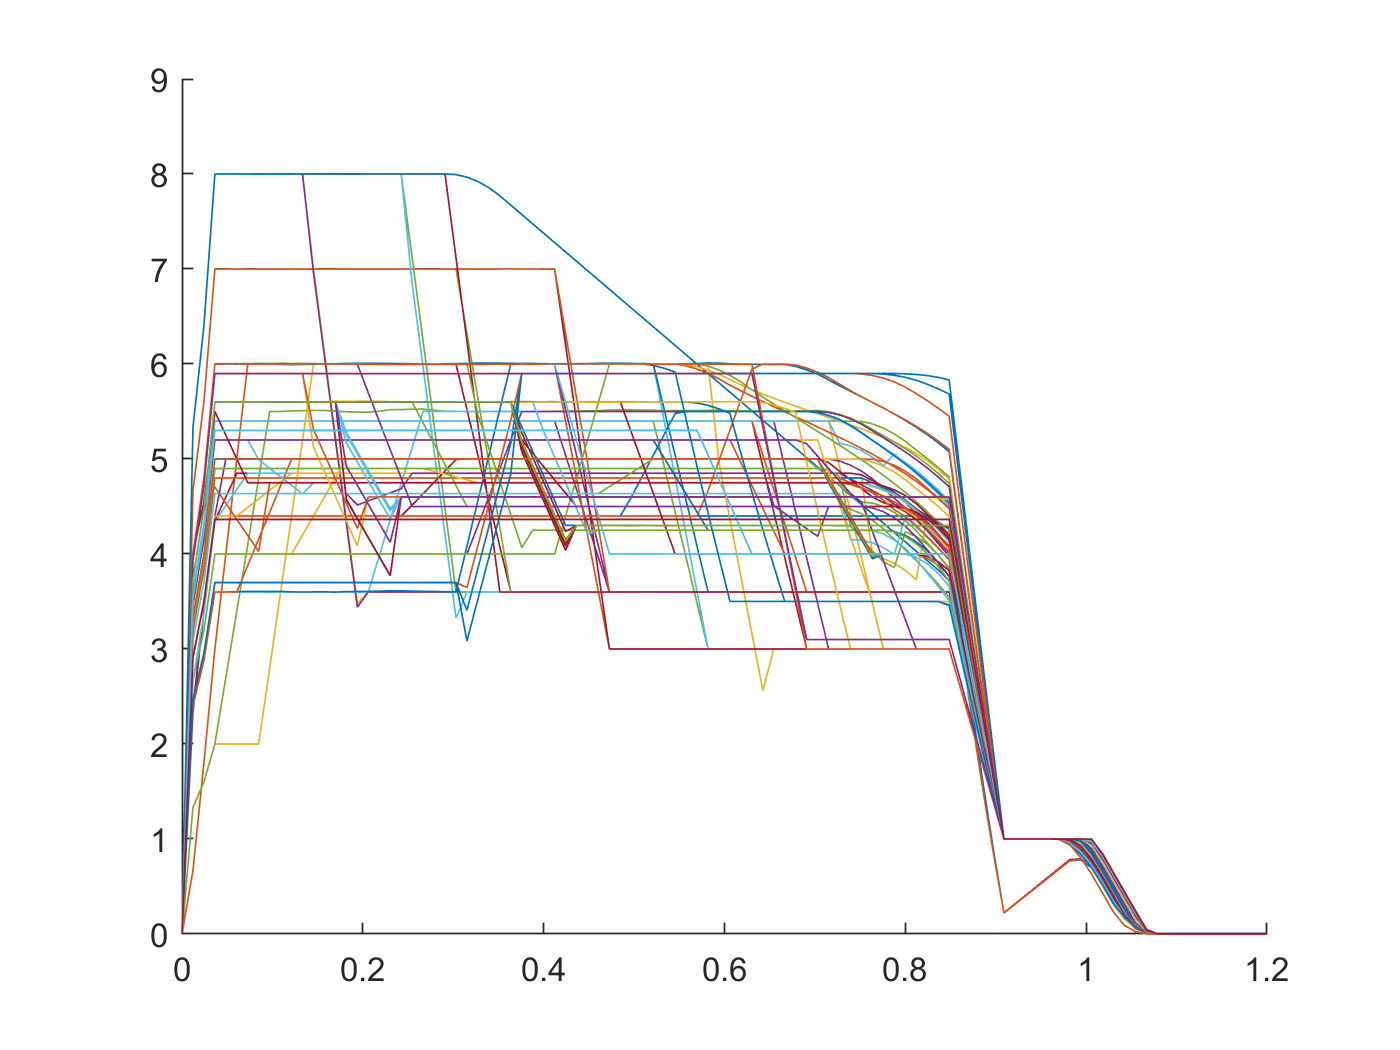


figure, hold on
for i = 1 : length(IcFirst)
    %if rem(i,2) == 0
    plot(chargeCurrentIndex,smooth(IcFirst(i,:))) % movmean
    %end 
end
hold off


%IcFirst = IcFirst'
idx=idxAll;
cycleLife = [battery_dataset(idx).cycle_life ]'

cycleLife =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x = IcFirst

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

%x=Ic
y = cycleLife

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);



IcFirst

IcFirst =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.800

%{
% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.
meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))
IcFirstSmall = blockproc(IcFirst, blockSize, meanFilterFunction)
check1 = 0	+ 4.39981019088461 + 	4.40021996012301	+  4.40016441450076 +	4.40028052631599
check1 = check1 /5 

check2 = 0	+ 4.79984935638003	+ 4.80010278673953	+ 4.80019086870934	+ 4.80000036603629
check2 = check2 /5 


[rows, columns] = size(IcFirstSmall)

%}

min(y)

ans = 109

max(y)

ans = 1171


yrate =  max(y) - min(y)

yrate = 1062

ymin = min(y)

ymin = 109

ynorm = (y - ymin) / yrate

ynorm =     0.3004
    0.1130
    0.1356
    0.2156
    0.2891
    0.2090
    0.1591
    0.1186
    0.1648
    0.3324


yback = ynorm * yrate + ymin

yback = 	1.0e+03 *

    0.4280
    0.2290
    0.2530
    0.3380
    0.4160
    0.3310
    0.2780
    0.2350
    0.2840
    0.4620


y

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

min(min(x))

ans = 0

max(max(x))

ans = 8.0061

xrate =  max(max(x)) - min(min(x))

xrate = 8.0061

xmin = min(min(x))

xmin = 0

xnorm = (x - xmin) / xrate

xnorm =          0    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5495    0.5496    0.5496    0.5496    0.5496    0.5496    0.5496    0.5495    0.5496    0.5496    0.5496    0.5495    0.5497    0.5495    0.5495    0.5496    0.5496    0.5495    0.5496    0.5496    0.5496    0.5496    0.5497    0.5496
         0    0.5995    0.5996    0.5996    0.5995    0.5996    0.5995    0.5995    0.5996    0.5996    0.5995    0.5995    0.5996    0.5995    0.5995    0.5996    0.5995    0.5996    0.5995    0.5995    0.5995    0.5995    0.5995    0.5996    0.5995    0.5995    0.5995    0.5996    0.5996    0.5995    0.5996    0.5996    0.5995    0.5995    0.5995    0.5995    0.5996    0.5995    0.5996    0.5996    0.5995    0.5995    0.5995    0.5996    0.5996    0.5996    0.5996    0.5996    0.5995 

xback = xnorm * xrate + xmin

xback =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001 

x

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

%{
%cycle = cycle -1;
%cycle_data = [cycle key policy policy_readable];
cycle_data = [cycle key policy_str policy_readable_str];
cycleTable1 = array2table(cycle_data,...
    'VariableNames',{'cycle','key','policy','policy_readable'})
cycleTable = table(cycle, key, policy_str, policy_readable_str,Ic)
cycleTableSort = sortrows(cycleTable,1,'descend')
%}

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

%x = IcFirstSmall
x = IcFirst
y = cycleLife
[ynorm,xnorm] = minmax_norm_new_with_param(y,x,ymin,yrate,xmin,xrate);

%x_trainValid = xnorm([idxTrain idxValid],:)
x_trainValid = xnorm([idxTrain ],:)

x =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4.8001    4

%x_test = xnorm([idxTest],:)

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x_test = xnorm([idxTest idxValid],:)

%y_trainValid = ynorm([idxTrain idxValid])
y_trainValid = ynorm([idxTrain])

x_trainValid =          0    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.7494    0.7494    0.7495    0.7495    0.7494    0.7494    0.7494    0.7494    0.7495    0.7493    0.7494    0.7493    0.7494    0.7453    0.7493    0.7495    0.7492    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7494    0.7495    0.7495    0.7494    0.7496    0.7495    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7495    0.7451    0.7351
         0    0.7490    0.7501    0.7494    0.7494    0.7505    0.7496    0.7489    0.7494    0.7510    0.7487    0.7506    0.7487    0.7490    0.7497    0.7505    0.7506    0.7510    0.7496    0.7501    0.7507    0.7491    0.7507    0.7483    0.7483    0.7507    0.7506    0.7514    0.7497    0.7507    0.7506    0.7507    0.7494    0.7495    0.7503    0.7488    0.7507    0.7501    0.7494    0.7511    0.7508    0.7506    0.7504    0.7481    0.7483    0.7406    0.7319    0.7248    

%y_test = ynorm([idxTest])
y_test = ynorm([idxTest idxValid])

x_test =          0    0.7493    0.7493    0.7494    0.7497    0.7496    0.7484    0.7494    0.7488    0.7493    0.7487    0.7489    0.7499    0.7494    0.7494    0.7493    0.7492    0.7492    0.7479    0.7488    0.7488    0.7488    0.7483    0.7503    0.7490    0.7506    0.7495    0.7494    0.7492    0.7481    0.7508    0.7509    0.7491    0.7488    0.7498    0.7480    0.7495    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4996    0.4997    0.4997    0.4996    0.4996    0.4996
         0    0.4996    0.4996    0.4996    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6057    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058    0.6058

y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424



idxTrainRand_new = idxTrainRand(1:80);

y_test =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719


idxValidRand_new = idxTrainRand(81:end);
idxTestRand_new = [ idxValidRand idxTestRand]

- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainRand_new;

idxTestRand_new =     94    63   100    46   115    65    10    14    11    40    56    59    26   106    28    76   119    84    47    62    92    16    48    99


netFNN1_1.divideParam.valInd = idxValidRand_new;
netFNN1_1.divideParam.testInd = idxTestRand_new; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');
%tr

netFNN1_2 = feedforwardnet([100,100]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = tr.trainInd;
netFNN1_2.divideParam.valInd = tr.valInd;
netFNN1_2.divideParam.testInd = tr.testInd; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_2 = train(netFNN1_2, xnorm', ynorm', 'useparallel',  'yes');



netFNN1_3 = feedforwardnet([100,100,100]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = tr.trainInd;
netFNN1_3.divideParam.valInd = tr.valInd;
netFNN1_3.divideParam.testInd = tr.testInd; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_3, tr3] = train(netFNN1_3, xnorm', ynorm', 'useparallel',  'yes');


pFNN1_1 = netFNN1_1(xnorm(tr.testInd, :)');
pFNN1_2 = netFNN1_2(xnorm(tr.testInd, :)');
pFNN1_3 = netFNN1_3(xnorm(tr.testInd, :)');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.




ytest = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_1_hat = pFNN1_1 * yrate + ymin;
pFNN1_2_hat = pFNN1_2 * yrate + ymin;
pFNN1_3_hat = pFNN1_3 * yrate + ymin;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))
rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))
rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')

rmse_pFNN1_1_hat = 249.9302

plot(ytest,pFNN1_2_hat,'+')

rmse_pFNN1_2_hat = 195.7010

plot(ytest,pFNN1_3_hat,'*')

rmse_pFNN1_3_hat = 229.3755

% plot(ytest,pFNN2_1_hat,'.')
% plot(ytest,pFNN2_2_hat,'x')
% plot(ytest,pFNN3_1_hat,'_')
% plot(ytest,pFNN4_1_hat,'|')
% plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
'Location','northeastoutside')



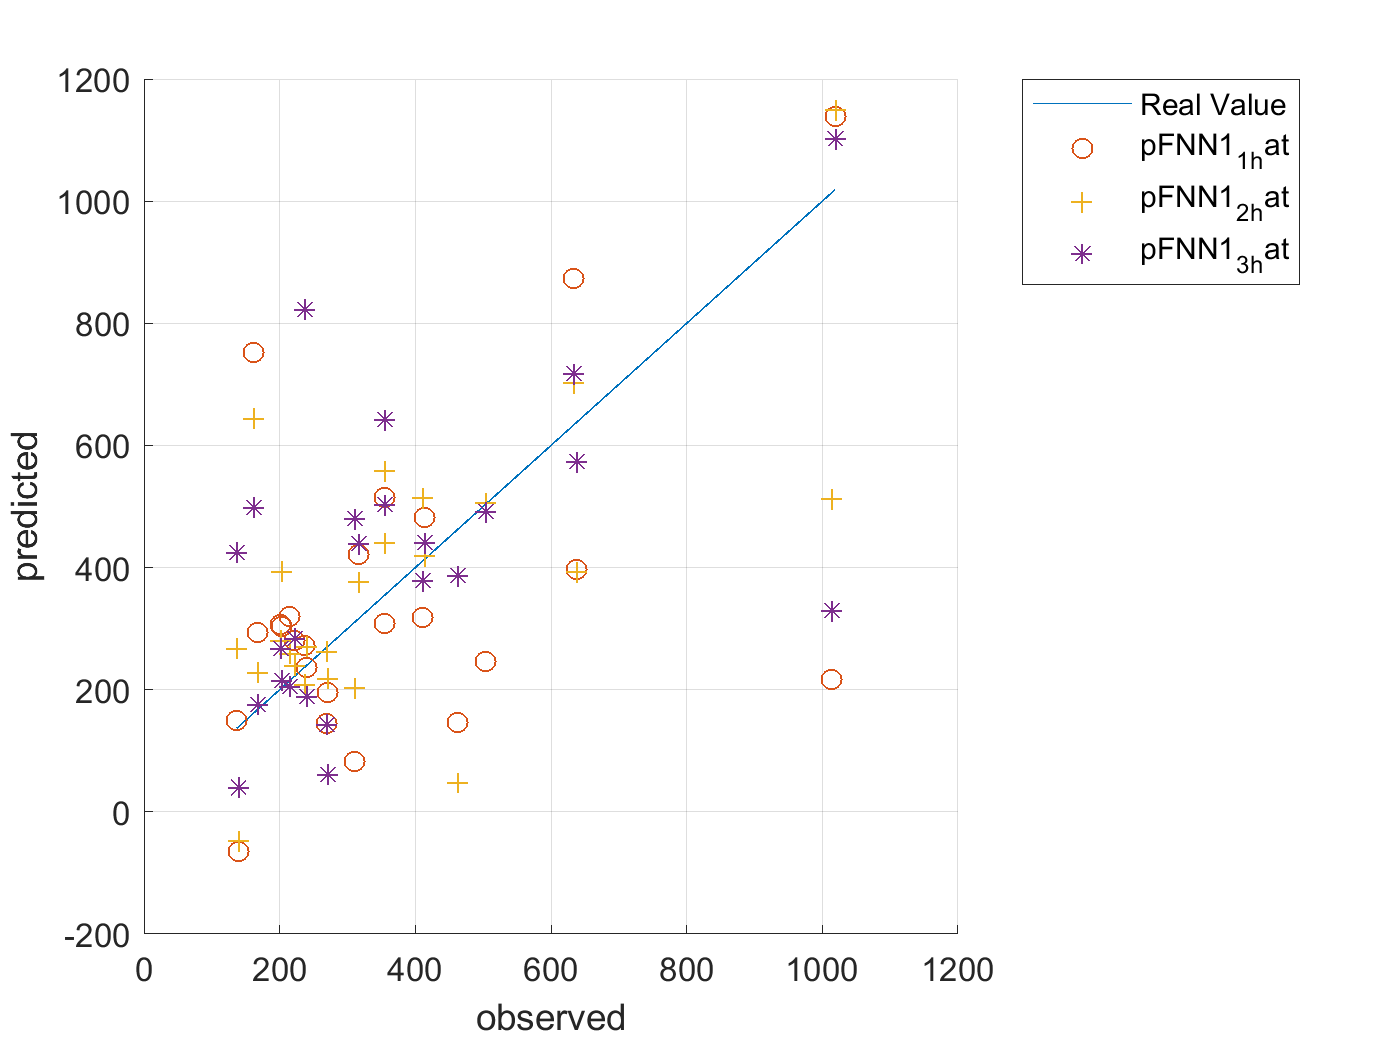

save('ryan3_model_1stCC_RUL_FNN.mat','netFNN1_1' )
save('ryan3_model_1stCC_RUL_FNN.mat','netFNN1_2' ,'-append')
save('ryan3_model_1stCC_RUL_FNN.mat','netFNN1_3' ,'-append')


pFNN1_1_self = netFNN1_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_2_self = netFNN1_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_3_self = netFNN1_3(xnorm([tr.trainInd tr.valInd], :)');


ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pFNN1_1_self_hat = pFNN1_1_self * yrate + ymin;
pFNN1_2_self_hat = pFNN1_2_self * yrate + ymin;
pFNN1_3_self_hat = pFNN1_3_self * yrate + ymin;



rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))
rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))
rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))




rmse_pFNN1_1_self_hat = 87.8538

figure, hold on, grid on,

rmse_pFNN1_2_self_hat = 100.8267

plot(ytrain_self,ytrain_self)

rmse_pFNN1_3_self_hat = 111.2262

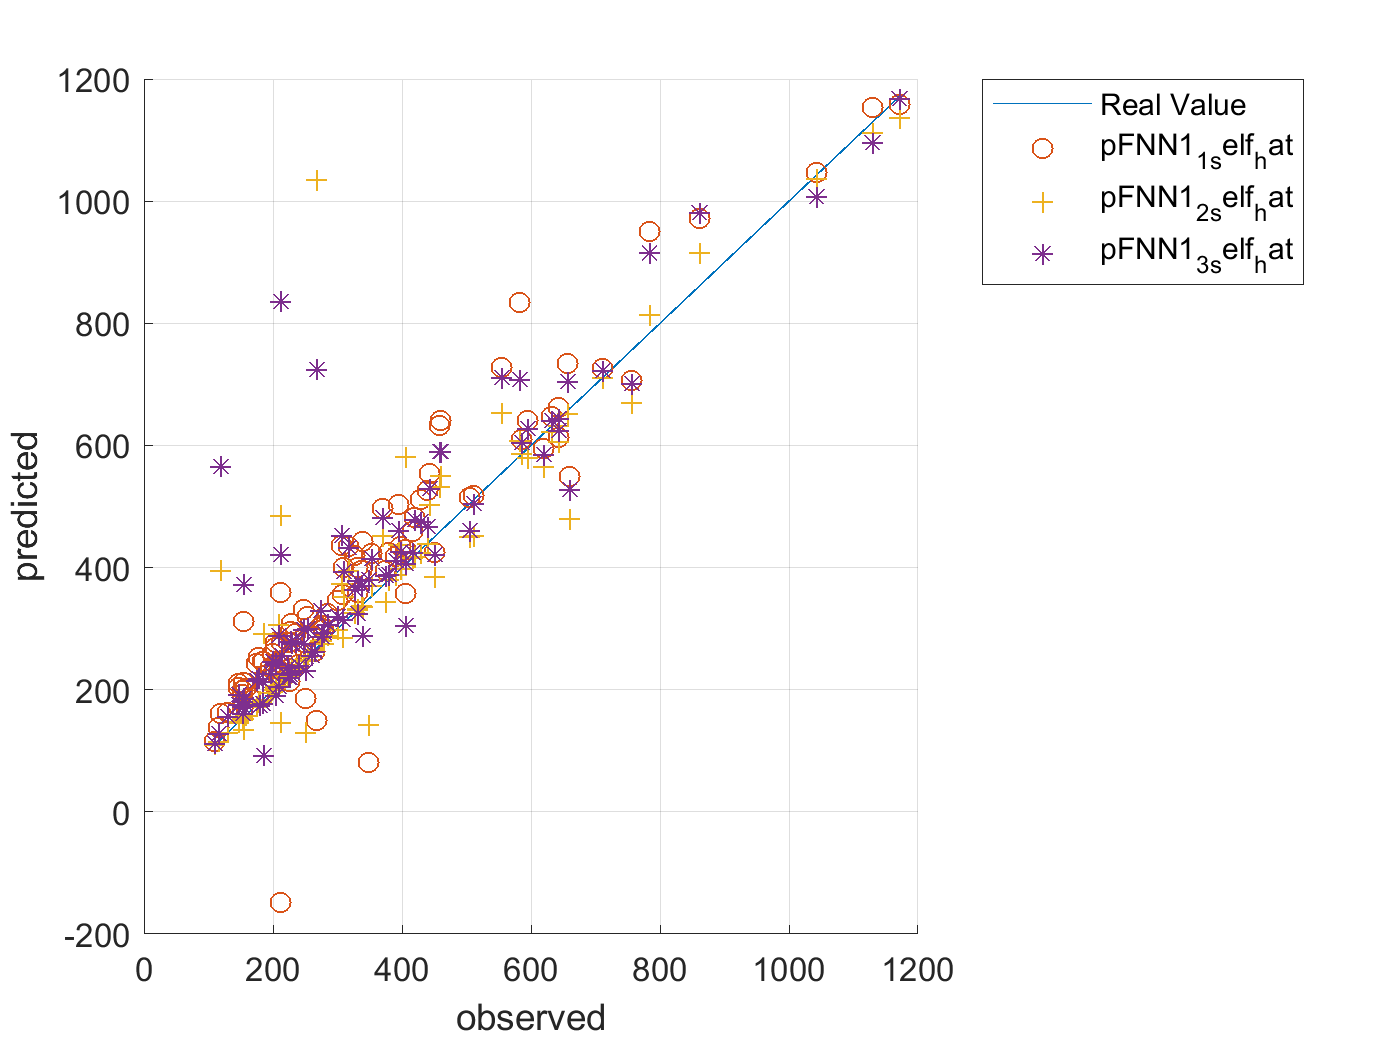

plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
% plot(ytrain_self,pFNN2_1_self_hat,'.')
% plot(ytrain_self,pFNN2_2_self_hat,'x')
% plot(ytrain_self,pFNN3_1_self_hat,'_')
% plot(ytrain_self,pFNN4_1_self_hat,'|')
% plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
'Location','northeastoutside')